clear;
%data
files = {
    'empty.csv'   % baseline
    'light b.csv'
    'light u.csv'
    'medium b.csv'
    'medium u.csv'
    'heavy b.csv'
    'heavy u.csv'
};

baselineIdx = 1;          % baseline index
useMagnitude = false;     % false = Z-axis

% peak settings
minPromFrac  = 0.05;
minPeakHzSep = 1;
fMin = 0;
fMax = 50;

%prealocate
nFiles = numel(files);
meanFreqs = nan(nFiles,1);

f_ss_all = cell(nFiles,1);
X_ss_all = cell(nFiles,1);
locs_all = cell(nFiles,1);
pks_all  = cell(nFiles,1);

% loop for dft in all files
for i = 1:nFiles

    % load
    try
        data = readtable(files{i});
    catch
        data = readtable(files{i}, 'Delimiter', '\t');
    end

    t  = data{:,1};
    ax = data{:,2};
    ay = data{:,3};
    az = data{:,4};

    % demean
    ax = ax - mean(ax,'omitnan');
    ay = ay - mean(ay,'omitnan');
    az = az - mean(az,'omitnan');

    % signal
    if useMagnitude
        x = sqrt(ax.^2 + ay.^2 + az.^2);
    else
        x = az;
    end

    % sampling
    dt = mean(diff(t),'omitnan');
    Fs = 1/dt;
    N  = length(x);

    % DFT
    x = x(:).';
    n = 0:N-1;
    X = zeros(N,1);

    for k = 0:N-1
        X(k+1) = sum(x .* exp(-1j*2*pi*k*n/N));
    end

    % spectrum
    f = (0:N-1)*(Fs/N);
    Xmag = abs(X)/N;

    halfN = floor(N/2)+1;
    f_ss = f(1:halfN);
    X_ss = Xmag(1:halfN);
    if halfN > 2
        X_ss(2:end-1) = 2*X_ss(2:end-1);
    end

    % peak analysis
    f_use = f_ss(2:end);
    X_use = X_ss(2:end);

    band = (f_use >= fMin) & (f_use <= fMax);
    f_band = f_use(band);
    X_band = X_use(band);

    if isempty(X_band)
        meanFreq = NaN;
        locs = [];
        pks = [];
    else
        minProm = minPromFrac * max(X_band);
        [pks, locs] = findpeaks(X_band, f_band, ...
            'MinPeakProminence', minProm, ...
            'MinPeakDistance', minPeakHzSep);

        if isempty(locs)
            meanFreq = NaN;
        else
            meanFreq = mean(locs);
        end
    end

    meanFreqs(i) = meanFreq;

    f_ss_all{i} = f_ss;
    X_ss_all{i} = X_ss;
    locs_all{i} = locs;
    pks_all{i}  = pks;
end

%means
for i = 1:nFiles
    fprintf('%-12s : %.3f\n', files{i}, meanFreqs(i));
end

empty.csv    : 31.109
light b.csv  : 33.045
light u.csv  : 28.360
medium b.csv : 30.792
medium u.csv : 29.235
heavy b.csv  : 28.105
heavy u.csv  : 26.986


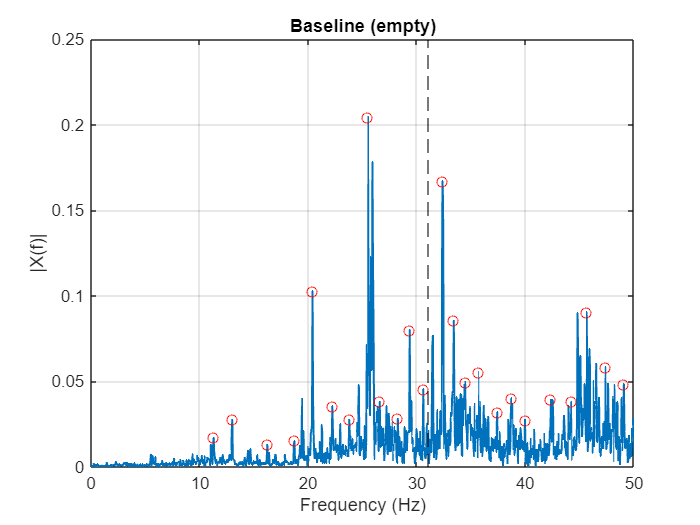


baselineMean = meanFreqs(baselineIdx);

%empty dft
figure;
plot(f_ss_all{baselineIdx}, X_ss_all{baselineIdx}, 'LineWidth',1.2);
grid on; hold on;
xlim([0 fMax]);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');

if ~isempty(locs_all{baselineIdx})
    plot(locs_all{baselineIdx}, pks_all{baselineIdx}, 'ro');
end
if ~isnan(meanFreqs(baselineIdx))
    xline(meanFreqs(baselineIdx), '--k');
end
title('Baseline (empty)');

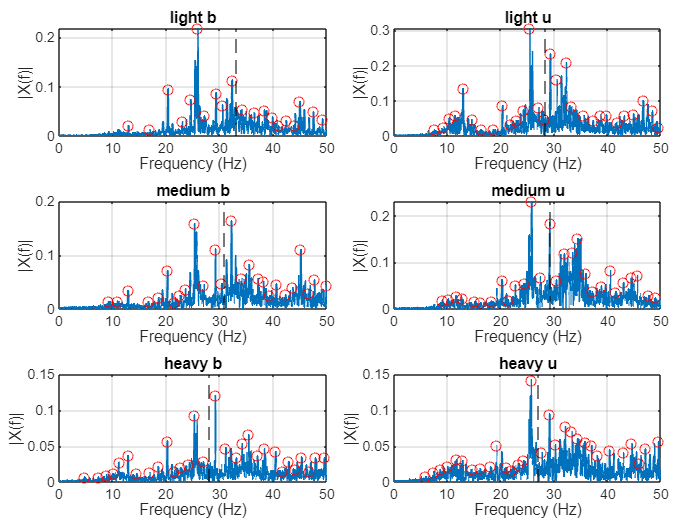


% dft for others
figure;
tiledlayout(3,2,'Padding','compact','TileSpacing','compact');

for i = 1:nFiles
    if i == baselineIdx
        continue;
    end

    nexttile;
    plot(f_ss_all{i}, X_ss_all{i}, 'LineWidth',1.2);
    grid on; hold on;
    xlim([0 fMax]);
    xlabel('Frequency (Hz)');
    ylabel('|X(f)|');

    if ~isempty(locs_all{i})
        plot(locs_all{i}, pks_all{i}, 'ro');
    end
    if ~isnan(meanFreqs(i))
        xline(meanFreqs(i), '--k');
    end

    [~, nm, ~] = fileparts(files{i});
    title(strrep(nm,'_','\_'));
end

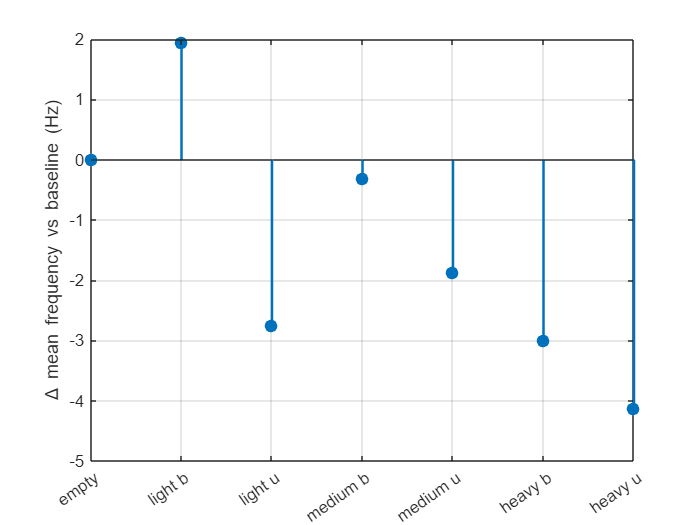


% comparsion plots based on the baseline
labels = cell(nFiles,1);
for i = 1:nFiles
    [~, nm, ~] = fileparts(files{i});
    labels{i} = nm;
end

x = 1:nFiles;
deltaMean = meanFreqs - baselineMean;
figure;
stem(x, deltaMean, 'filled', 'LineWidth',1.5);
grid on;
xticks(x);
xticklabels(labels);
xtickangle(35);

ylabel('\Delta mean frequency vs baseline (Hz)');
yline(0,'--');